Generated in MATLAB R2023a on by PLX & Luorong  2025-10-26 19:39:12

## Open the GUI window of Image Acquisition toolboxs

imageAcquisitionExplorer;
root_path = 'E:\1_Data\test';
mkdir(root_path)

device_list = {};

## Connect to Camera

Create connection to the device using the specified adaptor with the specified format.

info = imaqhwinfo('hamamatsu');
num_cameras = length(info.DeviceInfo);
fprintf('%0d camera(s) found.\n',num_cameras)

2 camera(s) found.


for i = 1:num_cameras
    dev_name = info.DeviceInfo(i).DeviceName;
    device_list{end+1} =dev_name;
    fprintf('Device ID %d: %s\n', i, dev_name);
end

Device ID 1: C14440-20UP, S/N: 002325, Bus: USB3
Device ID 2: C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8



v = cell(num_cameras,1);
src = cell(num_cameras,1);

for i = 1:num_cameras
    v{i} = videoinput("hamamatsu", i, "MONO16_2304x2304_Fast");
    src{i} = getselectedsource(v{i});
end

% if num_cameras == 1
%     v1 = videoinput("hamamatsu", 1, "MONO16_2304x2304_Fast");
% elseif  num_cameras == 2
%     v1 = videoinput("hamamatsu", 1, "MONO16_2304x2304_Fast");
%     v2 = videoinput("hamamatsu", 2, "MONO16_2304x2304_Fast");
% end
fprintf('Camera(s) linked.\n')

Camera(s) linked.


## Connect to DAQ

Create connection to the NI controler using the specified adaptor with the specified format.

### Camera 2326 

external trigger: `Dev1/port0/line9`

timing: User2/PFI4

### Camera 2325 

external trigger: `Dev1/port0/line10`

timing: PFI0

% set trigger mode
trigger = true;
camera_ports = {'port0/line9','port0/line10'};
camera_names = {'C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8';'C14440-20UP, S/N: 002325, Bus: USB3'}

camera_names = 2×1 cell array
    {'C14440-20UP, S/N: 002326, Bus: AS-FBD-2XCXP6-2PE8'}
    {'C14440-20UP, S/N: 002325, Bus: USB3'              }


% Create the object.
d = daq('ni');
docount = 0;
device = 'Dev1';
dinfo = daqlist("ni");
disp(dinfo{1,'DeviceInfo'});

ni: National Instruments(TM) PCIe-6353 (Device ID: 'Dev1')
   Analog input supports:
      7 ranges supported
      Rates from 0.1 to 1250000.0 scans/sec
      32 channels ('ai0' - 'ai31')
      'Voltage' measurement type
   
   Analog output supports:
      -5.0 to +5.0 Volts,-10 to +10 Volts ranges
      Rates from 0.1 to 2857142.9 scans/sec
      4 channels ('ao0','ao1','ao2','ao3')
      'Voltage' measurement type
   
   Digital IO supports:
      Rates from 0.1 to 10000000.0 scans/sec
      48 channels ('port0/line0' - 'port2/line7')
      'InputOnly','OutputOnly','Bidirectional' measurement types
   
   Counter input supports:
      Rates from 0.1 to 100000000.0 scans/sec
      4 channels ('ctr0','ctr1','ctr2','ctr3')
      'EdgeCount','PulseWidth','Frequency','Position' measurement types
   
   Counter output supports:
      Rates from 0.1 to 100000000.0 scans/sec
      4 channels ('ctr0','ctr1','ctr2','ctr3')
      'PulseGeneration' measurement type
   




addinput(d,'Dev1','ai0',"Voltage"); % dummy AI channel is necessary for setting the clock...
% addoutput(d,"Dev1","ctr0","PulseGeneration")

for i = 1:num_cameras
    indexC = strfind(camera_names, info.DeviceInfo(i).DeviceName); % 返回 {[1], [], []}
    index = find(~cellfun('isempty', indexC)); % 返回 [1]
    addoutput(d,'Dev1',camera_ports{index},'Digital');
    docount = docount + 1 ;
    dindex_cameras(i) = docount;
end
% dindex_cameras = [1:num_cameras]+1;

% do1 = addoutput(d,'Dev1','port0/line9','Digital');
% dindex_cameras = [1:num_cameras]+1;
%
% if num_cameras == 2
%     do2 = addoutput(d,'Dev1','port0/line10','Digital');
% end

% Set the sample rate to 10,000 Hz.
d.Rate = 1000;
% dindex_cameras = [1:num_cameras]+1;

registed = false;
videostim = false;


## Set light source

# Light intensity must be set in web app

### `Light source`

`Laser405 Dev1/port0/line23`

`Laser445 Dev1/port0/line11`

`LEDcyan Dev1/port0/line12`

`LEDgreen Dev1/port0/line16`

`LEDred Dev1/port0/line18`

channel_group = {'Laser405','Laser445','LEDcyan','LEDgreen','LEDred'};
channel = [3,5];% manually select used channel.

colors = {'m','b','b','g','r'};
light_port = {"port0/line23","port0/line11","port0/line12","port0/line16","port0/line18"};

usedlsrc = channel_group(channel);
imagelsrc = usedlsrc(end-num_cameras+1:end);
stimlsrc = setdiff(usedlsrc,imagelsrc);

num_imlsrc = length(imagelsrc); % num of imaging light source
num_stlsrc = length(stimlsrc); % num of stimulate light source;

if num_stlsrc >1
    warning('Stimulate light number > 1.\n')
end

% dindex_stimlsrc = [1:num_stlsrc] + num_cameras + 1;
% dindex_imlsrc = [1:num_imlsrc] + num_cameras + num_stlsrc + 1;


if length(d.Channels) > num_cameras+1
    docount = docount - length((num_cameras+2):length(d.Channels));
    removechannel(d,(num_cameras+2):length(d.Channels))
end

for i = 1:length(channel)
    addoutput(d,'Dev1',light_port{channel(i)},'Digital');
    docount = docount + 1 ;
    if i <= num_stlsrc
        dindex_stimlsrc(i) = docount;
    else
        dindex_imlsrc(i) = docount;
    end
end



fprintf('Light sources set as stimulate light: %s, imaging light: %s',cell2mat(stimlsrc),cell2mat(imagelsrc));

Light sources set as stimulate light: , imaging light: LEDcyanLEDred

## Set DMD

### DMD 

`Dev1/port0/line8`

addoutput(d,'Dev1','port0/line8','Digital');
docount = docount + 1 ;
num_DMD = 1; % num of stimulate light source;
dindex_DMD = [1:num_imlsrc] + num_cameras + num_stlsrc + num_imlsrc + 1;

## Align Two Cameras (if two cameras were used)

Snap photos by two cameras

% preset cameras
ROI{1} = [0 0 2304 2304];
ROI{2} = [0 0 2304 2304];

% v1.ROIPosition = ROI1;
% src1 = getselectedsource(v1);
% src1.ExposureTime = 20e-03;
% v1.FramesPerTrigger = 10;

v{1}.ROIPosition = ROI1;
src{1}.ExposureTime = 20e-03;

v{2}.ROIPosition = ROI2;
src{2}.ExposureTime = 20e-03;

% src2 = getselectedsource(v2);
% v2.FramesPerTrigger = 10;

Snap photos

% x = 0;
% y = 2;
% inputC = [zeros(d.Rate*2-x,num_cameras)];
% inputL = [ones(d.Rate*numSeconds-x,y);zeros(x,y)];
% input = cat(2,inputC,inputL);
% flush(d)
% preload(d,input)
% start(d)
% start(v1)
% if num_cameras == 2
%     start(v2)
% end
im25 = getsnapshot(v{1});
im26 = getsnapshot(v{2});
im25 = im25';

### Register images

fprintf('Registering images...\n')
tic;
registermode ='multimodal' ;
% 创建优化器和度量
[optimizer, metric] = imregconfig(registermode);
% optimizer.GradientMagnitudeTolerance = 1e-2;
% optimizer.MaximumStepLength = 10; % 增大最大步长，应对大偏移
% optimizer.MinimumStepLength = 1e-7; % 减小最小步长，提高最终精度
optimizer.MaximumIterations = 100;  % 增加迭代次数
optimizer.InitialRadius = 0.008;
% optimizer.RelaxationFactor = 0.3;   % 调整松弛因子，影响收敛速度

% % 执行配准
tform = imregtform(im25, im26, 'translation', optimizer, metric);
fprintf(sprintf('Registered after %0d s.\n',toc))
% 提取偏移量
x_offset = tform.T(3,1);
y_offset = tform.T(3,2);

fprintf('计算出的偏移量: x_offset = %.2f, y_offset = %.2f\n', x_offset, y_offset);
fprintf('centered camera2325 = %d, %d\n', round(896 - y_offset), round(896 - x_offset));

registered_im25 = imtranslate(im25, [x_offset,y_offset]);
% 显示配准结果
figure
subplot(1,3,1);
imshowpair(im25,im26);
title('配准前叠加');

% 应用变换
subplot(1,3,2);
imshowpair(registered_im25,im26);
title('配准后叠加');


### Apply offset

registed = true;
ROI{1} = [round(896 - y_offset) round(896 - x_offset) 512 512];
ROI{2} = [896 896 512 512];

v{1}.ROIPosition = ROI{1};
v{2}.ROIPosition = ROI{2};


### Reimaging

im25 = getsnapshot(v{1});
im26 = getsnapshot(v{2});
im25 = im25';

subplot(1,3,3);
imshowpair(im26, im25);
title('更换offset后重新拍摄');


fig_filename = fullfile(root_path, '0_register_image.fig');
png_filename = fullfile(root_path, '0_register_image.png');
mat_filename = fullfile(root_path, '0_register_image.mat');

saveas(gcf, fig_filename, 'fig');
saveas(gcf, png_filename, 'png');
save(mat_filename, 'registermode','optimizer','metric','x_offset','y_offset','tform');

## Configure Default Device Properties for Voltage Recording

Configure videoinput properties to prepare for acquisition.

triggermode = 'immediate'; % immediate 'manual'

if ~registed
    ROI{1} = [896 896 512 512];
    ROI{2} = [896 896 512 512];

end
eptime = 2.5e-03;

for i = 1:num_cameras
    v{i}.ROIPosition = ROI{i};
    v{i}.TriggerRepeat = 0;
    v{i}.FramesPerTrigger = Inf;
    src{i} = getselectedsource(v{i});
    src{i}.ExposureTime = eptime;
    triggerconfig(v{i}, triggermode);
    if trigger
        src{i}.TriggerSource = 'external';
        src{i}.TriggerPolarity = "negative";
        src{i}.TriggerMode = 'start';
    end
end

fprintf(sprintf('Camera(s) set to exposure time %d',eptime))

Camera(s) set to exposure time 2.500000e-03


% v1.ROIPosition = ROI1;
% v1.TriggerRepeat = 0;
% v1.FramesPerTrigger = Inf;
% src1 = getselectedsource(v1);
% src1.ExposureTime = eptime;
% triggerconfig(v1, triggermode);
% % config = triggerinfo(v1)
%
% if num_cameras == 2
%     v2.ROIPosition = ROI2;
%     v2.TriggerRepeat = 0;
%     v2.FramesPerTrigger = Inf;
%     src2 = getselectedsource(v2);
%     src2.ExposureTime = eptime;
%     triggerconfig(v2, triggermode);
% end

% if trigger
%     src1.TriggerSource = 'external';
%     src1.TriggerPolarity = "negative";
%     src1.TriggerMode = 'start';
%
%     % if num_cameras == 2
%     %     src2.TriggerSource = 'external';
%     %     src2.TriggerPolarity = "negative";
%     %     src2.TriggerMode = 'start';
%     % end
%
% end

## Screen stimulation preparation

### generate grafting drift video

% Define video resolution and parameters
videoWidth = 800;
videoHeight = 480;
frameRate = 30; % frames per second
ISI = 0.5; % s

% Create VideoWriter objects for saving videos
video_path = fullfile(root_path,'orientation_selective_gratings.avi');
gratingVideo = VideoWriter(video_path, 'Uncompressed AVI');

gratingVideo.FrameRate = frameRate;

open(gratingVideo);

% Create orientation-selective gratings video
orientations = 0:45:315; % 8 orientations (0°, 45°, ..., 315°)
spatialFrequency = 0.01; % cycles per division
temporalFrequency = 1.5; % Hz
gratingDuration = 0.5; % seconds per grating stimulus
numFramesPerGrating = round(gratingDuration * frameRate);
interFrame = ones(videoHeight,videoWidth) * 0.5;
cycles = 3;
for i = 1:cycles
    for orientationIdx = 1:length(orientations)
        % Loop over orientations and generate sinusoidal gratings
        theta = orientations(orientationIdx); % current orientation
        [X, Y] = meshgrid(1:videoWidth, 1:videoHeight);

        % Generate the grating pattern
        for t = 1:numFramesPerGrating
            % Calculate the phase shift for this frame
            phase = 2 * pi * temporalFrequency * (t / frameRate);

            % Create a sinusoidal grating pattern (motion effect)
            grating = 0.5 + 0.5 * sin(2 * pi * spatialFrequency * (X * cosd(theta) + Y * sind(theta)) - phase);

            % Write the frame to the video
            writeVideo(gratingVideo, grating);
        end

        for g = 1:ISI*frameRate

            writeVideo(gratingVideo, interFrame);
        end
    end
end

% Close video files

close(gratingVideo);

save(fullfile(root_path, 'orientation_gratings_parameters.mat'), ...
    'videoWidth', 'videoHeight', 'frameRate', 'ISI', ...
    'orientations', 'spatialFrequency', 'temporalFrequency', ...
    'gratingDuration', 'cycles', 'numFramesPerGrating', ...
    'interFrame', 'video_path');

disp('Videos generated successfully!');

Videos generated successfully!


# Please drop the video window to the side Screen manually.

### preset stim screen

screen = get(0,'MonitorPosition');
% f = figure('Position',screen(2,:), 'WindowState','fullscreen', 'MenuBar', 'none', 'Resize','off');

stimV = VideoReader(video_path);
FrameRate = stimV.FrameRate;
numFrames = stimV.NumFrames;
numSeconds = numFrames/FrameRate;

trails = zeros(1,numFrames);
videostim = true;

vp = vision.DeployableVideoPlayer();
vp(uint8(zeros(stimV.Height,stimV.Width,3)))
% h = imshow(zeros(stimV.Height,stimV.Width,3),'Border','tight');
frame = readFrame(stimV);
vp(frame)

### Link to gentl Camera

port0/line4

ginfo = imaqhwinfo('gentl');
if isempty(info.DeviceInfo)
    fprintf('no gentl camera found\n')
else
    vh = videoinput("gentl", 1, "Mono8");
    try
        addoutput(d,'Dev1','port0/line4','Digital');
        docount = docount + 1 ;
        dindex_hcamera = docount;
    end
end
Hikron = true;

vh.FramesPerTrigger = Inf;
srch = getselectedsource(vh);
srch.ExposureTime = 10;
triggerconfig(vh, triggermode);

## Input allocation

### Setting recording parameters

if ~videostim
    % nframes = 4000; % manually input
    % trecord = nframes*eptime;dinde
    trecord = 4000; % s
    nframes = trecord/eptime;
else
    nframes = numSeconds/eptime;
    trecord = numSeconds;
end

if Hikron
    nhframes = trecord*100;
end


% tcycles = ceil(trecord + trest); % to aviod last light shut frame.
% ttotal = tcycles*cycles;
tstim = 5; % second
tstimdelay = 2.5; %s

% dt = 0:1/d.Rate:ttotal-1/d.Rate;


% input = zeros(tcycles*d.Rate,length(d.Channels)-1);


## Camera input

docameras = zeros(trecord*d.Rate,num_cameras);

for i = 1:num_cameras
    docameras(:,i) = generateDigitalSignal('clock', 1/trecord, d.Rate, trecord);
end

## Light Stimulation input

if num_stlsrc > 0
    dostimlsrc = generateDigitalSignal('pulse', 1/trecord, d.Rate, trecord,'pulseWidth',tstim,'phase',tstimdelay);
else
    dostimlsrc = [];
end

## Light Imaging input

doimlsrc = zeros(trecord*d.Rate,num_imlsrc);

for i = 1:num_imlsrc
    doimlsrc(:,i) = generateDigitalSignal('pulse', 1/trecord, d.Rate, trecord,'pulseWidth',trecord);
end

### Hikron Camera Input

if Hikron
    dohcamera = generateDigitalSignal('clock', 1/trecord, d.Rate, trecord);
else
    dohcamera = [];
end

## Allocate to DO input

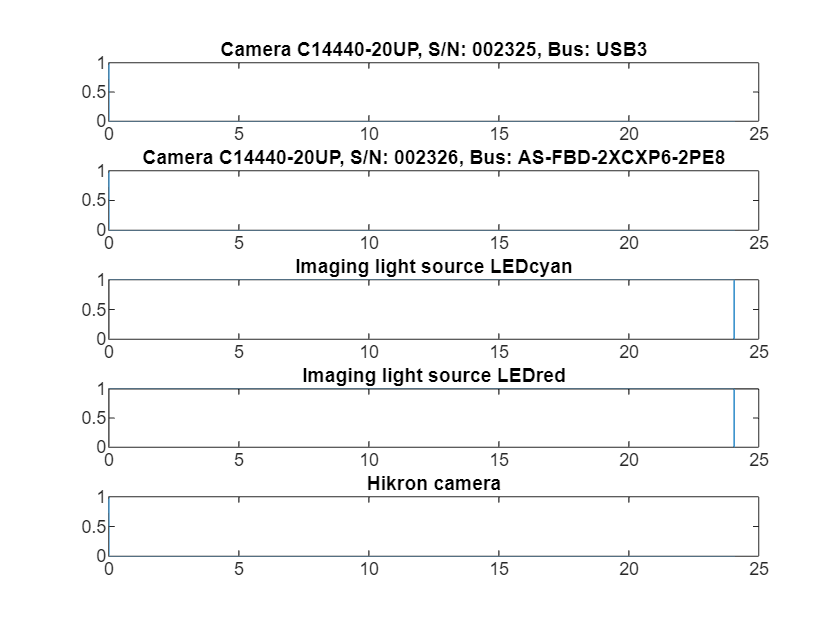

input = [docameras, dostimlsrc, doimlsrc,dohcamera];
% halftail = 0.1; % s;
% tailon = [zeros(halftail*d.Rate,num_cameras+num_stlsrc) ones(halftail*d.Rate,num_imlsrc)];
% tailoff = zeros(halftail*d.Rate,num_cameras+num_stlsrc+num_imlsrc);
taillength = 0.1;% s
tail = zeros(taillength*d.Rate,length(d.Channels)-1);
tail(1:taillength*d.Rate/2,dindex_imlsrc(1):dindex_imlsrc(end)) = 1;
%
% input = [input;tailon;tailoff];
input = [input; tail];


dt = 0:1/d.Rate:(length(input)-1)/d.Rate;
figure()

for i = 1:num_cameras
    subplot(length(d.Channels)-1,1,dindex_cameras(i))
    plot(dt,input(:,dindex_cameras(i)))
    title(sprintf('Camera %s',info.DeviceInfo(i).DeviceName));
end

if num_stlsrc > 0
    subplot(length(d.Channels)-1,1,dindex_stimlsrc)
    plot(dt,input(:,dindex_stimlsrc))
    title(sprintf('Stimulate light source %s',stimlsrc{1}));
end

for i = 1:num_imlsrc
    subplot(length(d.Channels)-1,1,dindex_imlsrc(i))
    plot(dt,input(:,dindex_imlsrc(i)))
    title(sprintf('Imaging light source %s',imagelsrc{i}));
end

if Hikron > 0
    subplot(length(d.Channels)-1,1,dindex_hcamera)
    plot(dt,input(:,dindex_hcamera))
    title(sprintf('Hikron camera'));
end

saveas(gcf, fullfile(root_path, '0_DO_input.fig'), 'fig');
saveas(gcf, fullfile(root_path, '0_DO_input.png'), 'png');

save(fullfile(root_path, '0_DO_input.mat'),"input")

recordtimes = 0;
% figure()
% for i = 1:size(input,2)
%     if i <= num_cameras
%         input(:,i) = generateDigitalSignal('clock', 1/tcycles, d.Rate, tcycles);
%         subplot(size(input,2),1,i)
%         plot(dt,repmat(input(:,i),cycles,1))
%         title(sprintf('Camera %s',info.DeviceInfo(i).DeviceName));
%     else
%         input(:,i) = generateDigitalSignal('pulse', 1/tcycles, d.Rate, tcycles,'pulseWidth',trecord-1/d.Rate);
%         subplot(size(input,2),1,i)
%         plot(dt,repmat(input(:,i),cycles,1))
%         title(sprintf('Light source %s',channel_group{i+num_cameras+1}));
%     end
%
% end
% inputC = [ones(x,num_cameras);zeros(d.Rate*(numSeconds+1)-x,num_cameras)];
% inputL = [ones(d.Rate*(numSeconds+1)-x,y);zeros(x,y)];
% input = cat(2,inputC,inputL);

## Recording

# Preview in GUI must be OFF before recording

recordlabel = {'5%Cyan', '25%Red'};
recordtimes = recordtimes+1;

cycles = 1; % default 1 repeat recording cycles
trest = 0; % default 0

% movie{i} = [];
% movie2 = [];

tstart = tic;
tsave = 0;

for c = 1:cycles

    for i = 1:num_cameras
        save_path{i} = fullfile(root_path,[sprintf('Rec%d_%s_Camera%d',recordtimes,recordlabel{i},i) ]);
        mkdir(save_path{i})

        stop(v{i})
        v{i}.FramesPerTrigger = nframes+1;
        start(v{i})
    end
    if hikron
        vh.FramesPerTrigger = nhframes+1;
        start(vh)
    end
    fprintf("Camera(s) ready.")

   

    % stop(v1)
    % if num_cameras == 2
    %     stop(v2)
    % end
    % 
    % v1.FramesPerTrigger = nframes+1; % for first bad frame
    % start(v1)
    % 
    % if num_cameras == 2
    %     v2.FramesPerTrigger = nframes+1;
    %     start(v2)
    % end



    fprintf("DAQ ready.")


    stop(d)
    flush(d)
    % start(d) % worked with write(d,input) ##2
    preload(d,input) % worked with start(d) ##1
    % start(d) % worked with write(d,input) ##2

    i = 1;
    if videostim
        stimV = VideoReader(video_path);
        if i == 1
            tic;
            start(d) % ##1
            % readwrite(d,input); % ##2
            elapse = toc;
        end
        while hasFrame(stimV)
            tnow = toc;

            if tnow - elapse >  1/FrameRate
                frame = readFrame(stimV);
                vp(frame)
                if i == 1
                    delay = toc;
                end
                trails(i) = tnow-(i-1)/FrameRate;
                elapse = tnow;
                i = i + 1;
            end
        end
        pause(trest);
    else
        tic;
        if c >1
            tlag = toc(tsave);
            fprintf('%d s lagged for next cycle.', tlag);
        else
            tlag =0;
        end
        elapse = toc;

        % write(d,input); % ##2
        start(d) % ##1

        % wait(v1); pause(rest);
        pause(trecord)
    end
    toc
    tsave = tic;

    movie1 = getdata(v1, v1.FramesAvailable);
    movie1 = squeeze(movie1(:,:,2:end)); % delete first error frame
    if num_cameras == 2
        movie2 = getdata(v2, v2.FramesAvailable);
        movie2 = squeeze(movie2(:,:,2:end));
    end
    parfor i = 1:num_cameras
        if i == 1
            array2tif(movie1,fullfile(save_path{i},sprintf('%s recording cycles %d.tif',imagelsrc{1},c)));
        elseif i == 2
            array2tif(movie2,fullfile(save_path{i},sprintf('%s recording cycles %d.tif',imagelsrc{2},c)));
        end
    end

    % movie1 = getdata(v1, v1.FramesAvailable);
    % movie1 = squeeze(movie1(:,:,2:end)); % delete first error frame
    % array2tif(movie1,fullfile(save_path{1},sprintf('%s recording cycles %d.tif',imagelsrc{1},c)));
    %
    % if num_cameras == 2
    %     movie2 = getdata(v2, v2.FramesAvailable);
    %     movie2 = squeeze(movie2(:,:,2:end));
    %     array2tif(movie2,fullfile(save_path{2},sprintf('%s recording cycles %d.tif',imagelsrc{2},c)));
    %
    % end
    if trest > toc(tsave)
        fprintf('%d s for saved.', toc(tsave));
        pause(trest-toc(tsave))
    end
    stop(d)
    stop(v1)
    if num_cameras == 2
        stop(v2)
    end
end

toc(tstart);

## Online analysis

for i = num_cameras
    if i == 1
        movie = movie1;
    elseif i == 2
        movie = movie2;
    end

### Create map

    %% Create a map (optional)
    t1 = tic; % Start a timer
    fprintf('Creating a map...\n')
    % if the map cannot figure out active cells, please large the bin.
    bin = 1; % defined bin = 4

    [quick_map] = create_map(movie,size(movie,1),size(movie,2),bin);
    map = quick_map;

    % Visualize correlation coefficients as heatmap
    figure()
    imagesc(quick_map);
    colormap turbo;
    title('Sensitivity Map');
    axis image;
    colorbar;
    fig_filename = fullfile(save_path{i}, '0_Sensitivity_Map.fig');
    png_filename = fullfile(save_path{i}, '0_Sensitivity_Map.png');
    mat_filename = fullfile(save_path{i}, '0_Sensitivity_Map.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(mat_filename, 'map');


    t2 = toc(t1); % Get the elapsed time
    fprintf('Finished mask creating after %d s\n',round(t2))

### Cellpose for mask generatopm

    fprintf('cellpose running......\n');
    cp = cellpose(ExecutionEnvironment="gpu");

    movie_vol_2D = squeeze(mean(movie,3));
    avg_image  = (movie_vol_2D - min(movie_vol_2D(:))) / (max(movie_vol_2D(:)) - min(movie_vol_2D(:)));


    avgdia = 15;
    % gamma_image = imadjust(map,[],[],1.2); % recommend raise the gamma factor from 1 to 4.
    gamma_image = imadjust(avg_image,[],[],1.2); % recommend raise the gamma factor from 1 to 4.
    mask = segmentCells2D(cp, gamma_image , ImageCellDiameter = avgdia,CellThreshold = -2, FlowErrorThreshold = 2);% CellThreshold = -2, ,  FlowErrorThreshold = 2
    fprintf('%d cells are found.\n',max(mask(:)));
    figure()
    % 使用labeloverlay函数显示图像
    overlayImage = labeloverlay(gamma_image, mask,'Transparency', 0.6);
    % 显示结果
    imshow(overlayImage);
    title('cellpose mask');
    fig_filename = fullfile(save_path{i}, '0_cellpose_mask.fig');
    png_filename = fullfile(save_path{i}, '0_cellpose_mask.png');
    mat_filename = fullfile(save_path{i}, '0_cellpose_mask.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(mat_filename, 'mask');

### ROI selection

    %% Select ROI
    t1 = tic; % Start a timer
    figure()

    [rois, traces] = select_ROI(movie,'mask', mask,'map', map);
    nrois = max(rois.bwmask,[],'all');

    try
        bwmask = rois.bwmask;
    catch ME

    end
    traces_original = traces;

    % if do not need a map, run the following code:
    % map = [];
    % [bwmask, traces] = select_ROI(movie, nrows, ncols, t, mask, map);

    fig_filename = fullfile(save_path{i}, '1_raw_trace.fig');
    png_filename = fullfile(save_path{i}, '1_raw_trace.png');
    roi_filename = fullfile(save_path{i}, '1_raw_ROI.mat');

    saveas(gcf, fig_filename, 'fig');
    saveas(gcf, png_filename, 'png');
    save(roi_filename, 'rois','avg_image','traces');

    % h = msgbox('All rois saved.', 'Done', 'help');
    % uiwait(h);


    tif_filename = fullfile(save_path{i}, '1_Averaged.tif');

    tiffile = Tiff(tif_filename, 'w');

    tiffile.setTag('ImageLength', size(movie,2));
    tiffile.setTag('ImageWidth', size(movie,1));
    tiffile.setTag('Photometric', Tiff.Photometric.MinIsBlack);
    tiffile.setTag('BitsPerSample', 16);
    tiffile.setTag('SamplesPerPixel', 1);
    tiffile.setTag('RowsPerStrip', 16);
    tiffile.setTag('PlanarConfiguration', Tiff.PlanarConfiguration.Chunky);
    tiffile.setTag('Compression', Tiff.Compression.None);

    tiffile.setTag('Software', 'MATLAB');
    tiffile.write(uint16(movie_vol_2D));
    tiffile.writeDirectory();
    tiffile.close();
    delete(tiffile)
end

## CHECK

% save_file = fullfile('Recording.tif');
%
% array2tif(movie1,save_file);
figure
plot(0:eptime:eptime*(size(movie1,3)-1),normalize(squeeze(mean(mean(movie1,1),2)),'range'))
hold on;
if num_cameras==2
    plot(0:eptime:eptime*(size(movie2,3)-1),normalize(squeeze(mean(mean(movie2,1),2)),'range'))
end
stimV  = VideoReader(video_path);
stmovie = read(stimV,[1 Inf]);
stmovie = squeeze(stmovie(1,1,:,:));
curvestim = plot(0:1/FrameRate:(size(stmovie,2)-1)/FrameRate,normalize(stmovie(1,:),'range'));
% disp(delay);
% realstim = plot((0:1/FrameRate:(size(stmovie,2)-1)/FrameRate)+delay,normalize(stmovie(1,:),'range'));
% legend("Camera2325",'Camera2326','Yellowlight')
legend('Camera2326','Bluelight')
% title("simutaneously recording by 2 cameras via cube set 1")

figure
plot(trails)